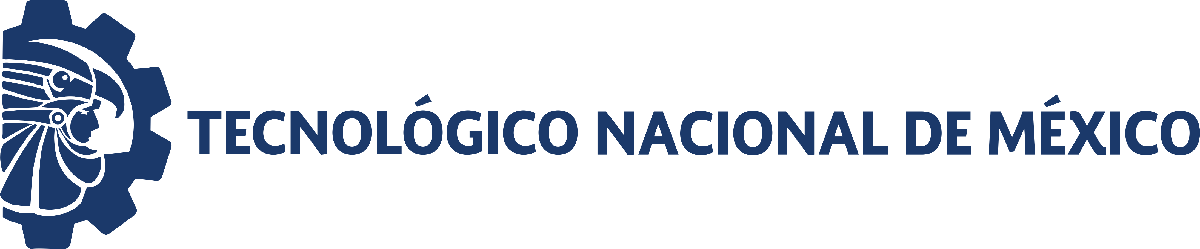                                 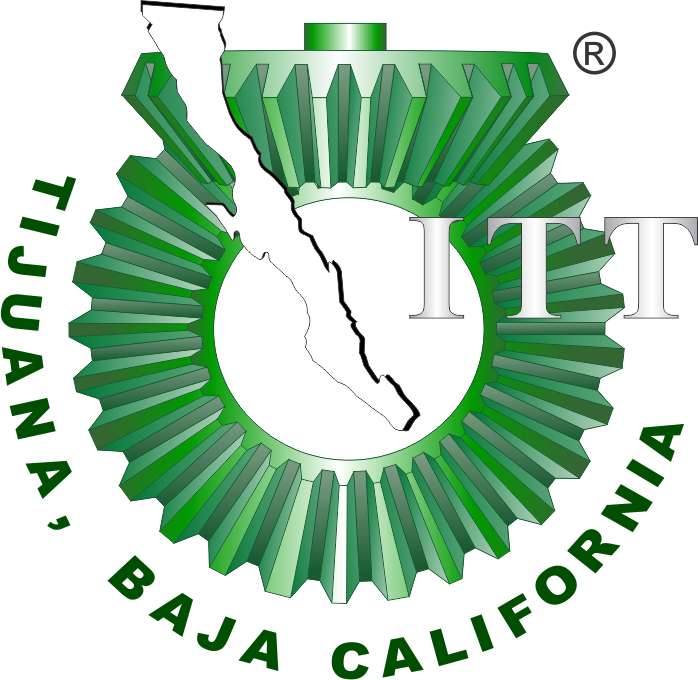

# Práctica uno: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

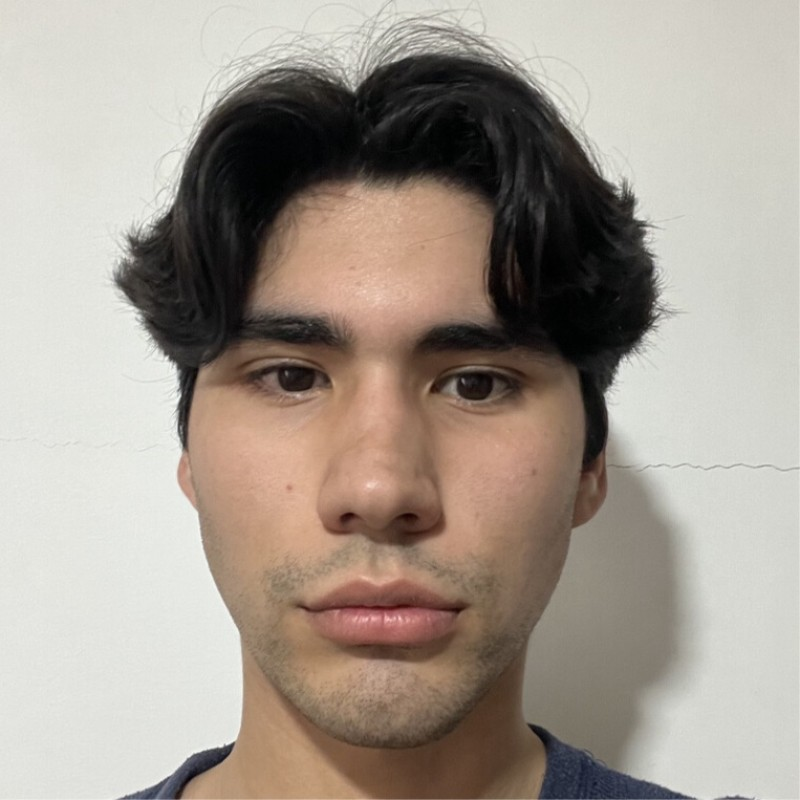

Nombre del alumno: Alberto Villalobos Valdez

Número de control: 22212277

Correo institucional: L22212277**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

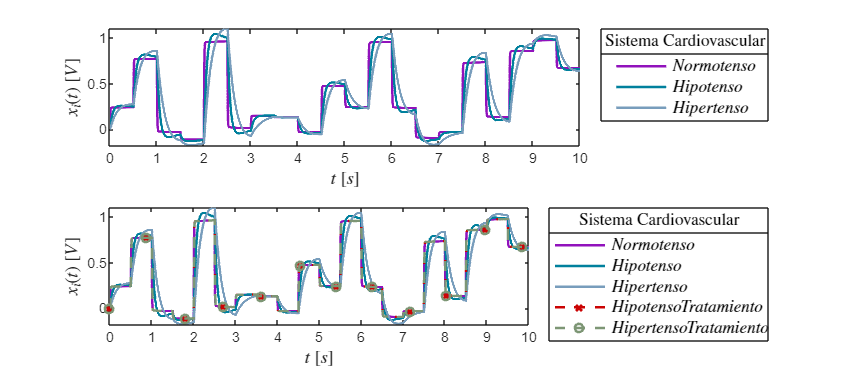

clc; clear; close all; warning('off','all');
tend = '10';
file = 'sistemaa';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = "ode23t";
parameters.MaxStep = '1E-3';
set_param('sistemaa/Ppa(t)','Minimum','-0.2');
set_param('sistemaa/Ppa(t)','Maximum','1');
set_param('sistemaa/Ppa(t)','Seed','106');
set_param('sistemaa/Ppa(t)','SampleTime','0.5');
x1=sim(file,parameters);
writematrix(x1.Ppa, 'signal.xlsx')
plotsignals(x1.t,x1.Pp0,x1.Pp1,x1.Pp2,x1.Pp3,x1.Pp4);

## Funcion : Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4)
    set(figure(), 'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    
    mycolors=[145,18,188;
        0,128,157;
        120,157,188;
        203,4,4;
        125,150,117;
        0,0,1]/255;

    colororder(mycolors)
    subplot(2,1,2);
    p=(plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,'--o',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t)));
    L= legend('$Normotenso$','$Hipotenso$','$Hipertenso$','$Hipotenso Tratamiento$','$Hipertenso Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Sistema Cardiovascular', 'FontSize',10)
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10);
    subplot(2,1,1);
    p2=(plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t)));
    L= legend('$Normotenso$','$Hipotenso$','$Hipertenso$','$Hipotenso Tratamiento$','$Hipertenso Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Sistema Cardiovascular', 'FontSize',10)
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10);


    exportgraphics(gcf,['SistemaCV3.pdf'],'ContentType','vector');
    exportgraphics(gcf,['SistemaCV3.png'],'ContentType','vector');
 
end


